clear all;
figure;

%image = imread("TrainingPictures\RoadSituation_30kmh_Round_Building_Sunny_1.png");
%image = imread("TrainingPictures\RoadSituation_30kmh_Round_Vegetation_Sunny_1.png");
image = imread("TrainingPictures\RoadSituation_50kmh_Round_Vegetation_Sunny_1.png");

tic
image_red = uint8(image(:, :, 1) - 1/2 * (image(:, :, 2) + image(:, :, 3)));

% fill all objects and binarize
image_red_bin = imbinarize(image_red, 'adaptive', 'Sensitivity', 0);
image_red_filled = imfill(image_red_bin, 'holes');

% get properties of circular objects
objects = regionprops('table', image_red_filled, "Circularity", "FilledArea", "BoundingBox");
objects = sortrows(objects, "FilledArea");

% get the first most matching objects
NUM_MATCHING_OBJECTS = 10;
if height(objects) < NUM_MATCHING_OBJECTS
    NUM_MATCHING_OBJECTS = height(objects)
end

filtered_objects = objects(end-NUM_MATCHING_OBJECTS+1:end, :);
toc

Elapsed time is 0.932239 seconds.



% get most round object
diff_circularity = abs(filtered_objects(:, :).Circularity - 1);
objects_circularity = table((1:height(filtered_objects))', filtered_objects(:, :).Circularity, diff_circularity, 'VariableNames', {'id', 'circularity', 'diff_circularity'});
objects_circularity = sortrows(objects_circularity, "diff_circularity");
object_of_choice_id = objects_circularity(1, :).id;
toc

Elapsed time is 1.025289 seconds.


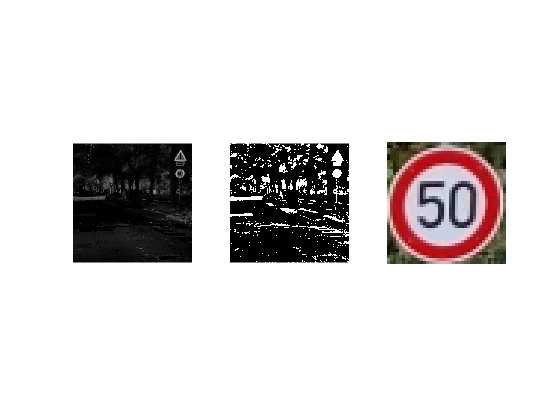

x       = int16(filtered_objects(object_of_choice_id, :).BoundingBox(1));
y       = int16(filtered_objects(object_of_choice_id, :).BoundingBox(2));
width   = int16(filtered_objects(object_of_choice_id, :).BoundingBox(3));
height  = int16(filtered_objects(object_of_choice_id, :).BoundingBox(4));
boxed_image = image(y:y+height, x:x+width, :);
subplot(1,3,1), imshow(image_red);
subplot(1,3,2), imshow(image_red_filled);
subplot(1,3,3), imshow(boxed_image);